%%%%%%% Projet : Classification d'Images pour la Reconnaissance d'Objets (CIFAR-10)
% Montassar Laboudi & Eya Sahli
%%%%%%% Partie évaluation de : GoogLeNet ---- Transfer Learning  
%%%%%%% DROP FACTOR 0.5 | EACH 3 EPOCHS 

%% 1. Téléchargement et Préparation des Données CIFAR-10
cifar10DataFolder = './cifar10Data';

if ~exist(cifar10DataFolder, 'dir')
    disp('Téléchargement des données CIFAR-10...');
    cifar10URL = 'https://www.cs.toronto.edu/~kriz/cifar-10-matlab.tar.gz';
    websave('cifar10Dataset.tar.gz', cifar10URL);
    untar('cifar10Dataset.tar.gz', cifar10DataFolder);
    disp('Téléchargement et extraction terminés.');
else
    disp('Données CIFAR-10 déjà disponibles.');
end

Données CIFAR-10 déjà disponibles.



% Charger les fichiers batch d'entraînement
trainImages = [];
trainLabels = [];
for batchIdx = 1:5
    batchFile = fullfile(cifar10DataFolder, 'cifar-10-batches-mat', sprintf('data_batch_%d.mat', batchIdx));
    batchData = load(batchFile);
    % Reshape des données : [3072 x N] -> [32 32 3 N]
    trainImages = cat(4, trainImages, reshape(batchData.data', [32, 32, 3, size(batchData.data, 1)]));
    trainLabels = [trainLabels; batchData.labels];
end

% Charger le batch de test
testBatchFile = fullfile(cifar10DataFolder, 'cifar-10-batches-mat', 'test_batch.mat');
testBatchData = load(testBatchFile);
testImages = reshape(testBatchData.data', [32, 32, 3, size(testBatchData.data, 1)]);
testLabels = testBatchData.labels;

% Correction des noms des classes
classNames = ["airplane", "automobile", "bird", "cat", "deer", "dog", "frog", "horse", "ship", "truck"];

% Conversion des labels en catégories
trainLabels = categorical(trainLabels, 0:9, classNames);
testLabels = categorical(testLabels, 0:9, classNames);

disp('Chargement des données CIFAR-10 terminé.');

Chargement des données CIFAR-10 terminé.



%% 2. Préparation des Données

% Définir la taille d'entrée pour GoogLeNet
inputSize = [224, 224, 3];

% Redimensionnement des images d'entraînement
numTrainImages = size(trainImages, 4);
trainImagesResized = zeros([inputSize, numTrainImages], 'like', trainImages);
for i = 1:numTrainImages
    trainImagesResized(:,:,:,i) = imresize(trainImages(:,:,:,i), inputSize(1:2), 'bicubic');
end

% Redimensionnement des images de test
numTestImages = size(testImages, 4);
testImagesResized = zeros([inputSize, numTestImages], 'like', testImages);
for i = 1:numTestImages
    testImagesResized(:,:,:,i) = imresize(testImages(:,:,:,i), inputSize(1:2), 'bicubic');
end

% Création de l'augmentedImageDatastore pour le jeu de test
testData = augmentedImageDatastore(inputSize, testImagesResized);

% Séparation du jeu d'entraînement en ensembles entraînement et validation
rng(2001); 
idx = randperm(numTrainImages);
numVal = floor(0.2 * numTrainImages);
numTrainFinal = numTrainImages - numVal;

% Extraction pour l'entraînement
trainImagesFinal = trainImagesResized(:,:,:, idx(1:numTrainFinal));
trainLabelsFinal = trainLabels(idx(1:numTrainFinal));

% Extraction pour la validation
valImages = trainImagesResized(:,:,:, idx(numTrainFinal+1:end));
valLabels = trainLabels(idx(numTrainFinal+1:end));

% Création des datastores pour l'entraînement et la validation
trainData = augmentedImageDatastore(inputSize, trainImagesFinal, trainLabelsFinal);
valData   = augmentedImageDatastore(inputSize, valImages, valLabels);

disp('Préparation des données terminée.');

Préparation des données terminée.



%% 3. Chargement du Modèle GoogLeNet et Gel de 50% des Couches Apprenables

% Charger GoogLeNet pré-entraîné
net = googlenet;
lgraph = layerGraph(net);

% Remplacer les couches finales pour l'adaptation à CIFAR-10
newFcLayer = fullyConnectedLayer(10, 'Name', 'new_fc', ...
    'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10);
newOutputLayer = classificationLayer('Name', 'new_output');
lgraph = replaceLayer(lgraph, 'loss3-classifier', newFcLayer);
lgraph = replaceLayer(lgraph, 'output', newOutputLayer);

% Identification des indices des couches avec des paramètres apprenables
learnableLayerIndices = [];
for i = 1:numel(lgraph.Layers)
    layer = lgraph.Layers(i);
    if isprop(layer, 'WeightLearnRateFactor') || isprop(layer, 'BiasLearnRateFactor')
        learnableLayerIndices(end+1) = i;
    end
end

% Affichage du nombre de couches apprenables détectées
numLearnable = numel(learnableLayerIndices);
fprintf('Nombre de couches apprenables dans GoogLeNet : %d\n', numLearnable);

Nombre de couches apprenables dans GoogLeNet : 58



% Déterminer 50% de ces couches pour le gel
numFreeze = floor(numLearnable / 2);
fprintf('Gel de %d couches sur %d (soit environ 50%% des couches apprenables)\n', numFreeze, numLearnable);

Gel de 29 couches sur 58 (soit environ 50% des couches apprenables)



% Gel des premières 50% des couches apprenables
for k = 1:numFreeze
    idxLayer = learnableLayerIndices(k);
    layer = lgraph.Layers(idxLayer);
    
    % Geler les paramètres d'apprentissage
    if isprop(layer, 'WeightLearnRateFactor')
        layer.WeightLearnRateFactor = 0;
    end
    if isprop(layer, 'BiasLearnRateFactor')
        layer.BiasLearnRateFactor = 0;
    end
    
    % Pour les couches de Batch Normalization
    if isa(layer, 'nnet.cnn.layer.BatchNormalizationLayer')
        layer.ScaleLearnRateFactor = 0;
        layer.OffsetLearnRateFactor = 0;
    end
    
    % Mise à jour de la couche dans le layerGraph
    lgraph = replaceLayer(lgraph, layer.Name, layer);
end

% Visualiser l'architecture modifiée
analyzeNetwork(lgraph);

%% 4. Entraînement du Modèle GoogLeNet
options = trainingOptions('adam', ...
    'MaxEpochs', 30, ... 
    'MiniBatchSize', 128, ...
    'InitialLearnRate', 0.001, ... 
    'LearnRateSchedule', 'piecewise', ...
    'LearnRateDropFactor', 0.5, ...
    'LearnRateDropPeriod', 3, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', valData, ...
    'ValidationFrequency', 312, ... 
    'Verbose', true, ...
    'Plots', 'training-progress', ...
    'ExecutionEnvironment', 'gpu', ...
    'ValidationPatience', 2);

disp('Entraînement de GoogLeNet en cours...');

Entraînement de GoogLeNet en cours...


Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:06 |        7.81% |       11.27% |       4.4912 |       4.4685 |          0.0010 |
|       1 |          50 |       00:02:02 |       49.22% |              |       1.5411 |              |          0.0010 |
|       1 |         100 |       00:02:55 |       65.62% |              |       1.0692 |              |          0.0010 |
|       1 |         150 |       00:03:51 |       66.41% |              |       1.0491 |              |          0.

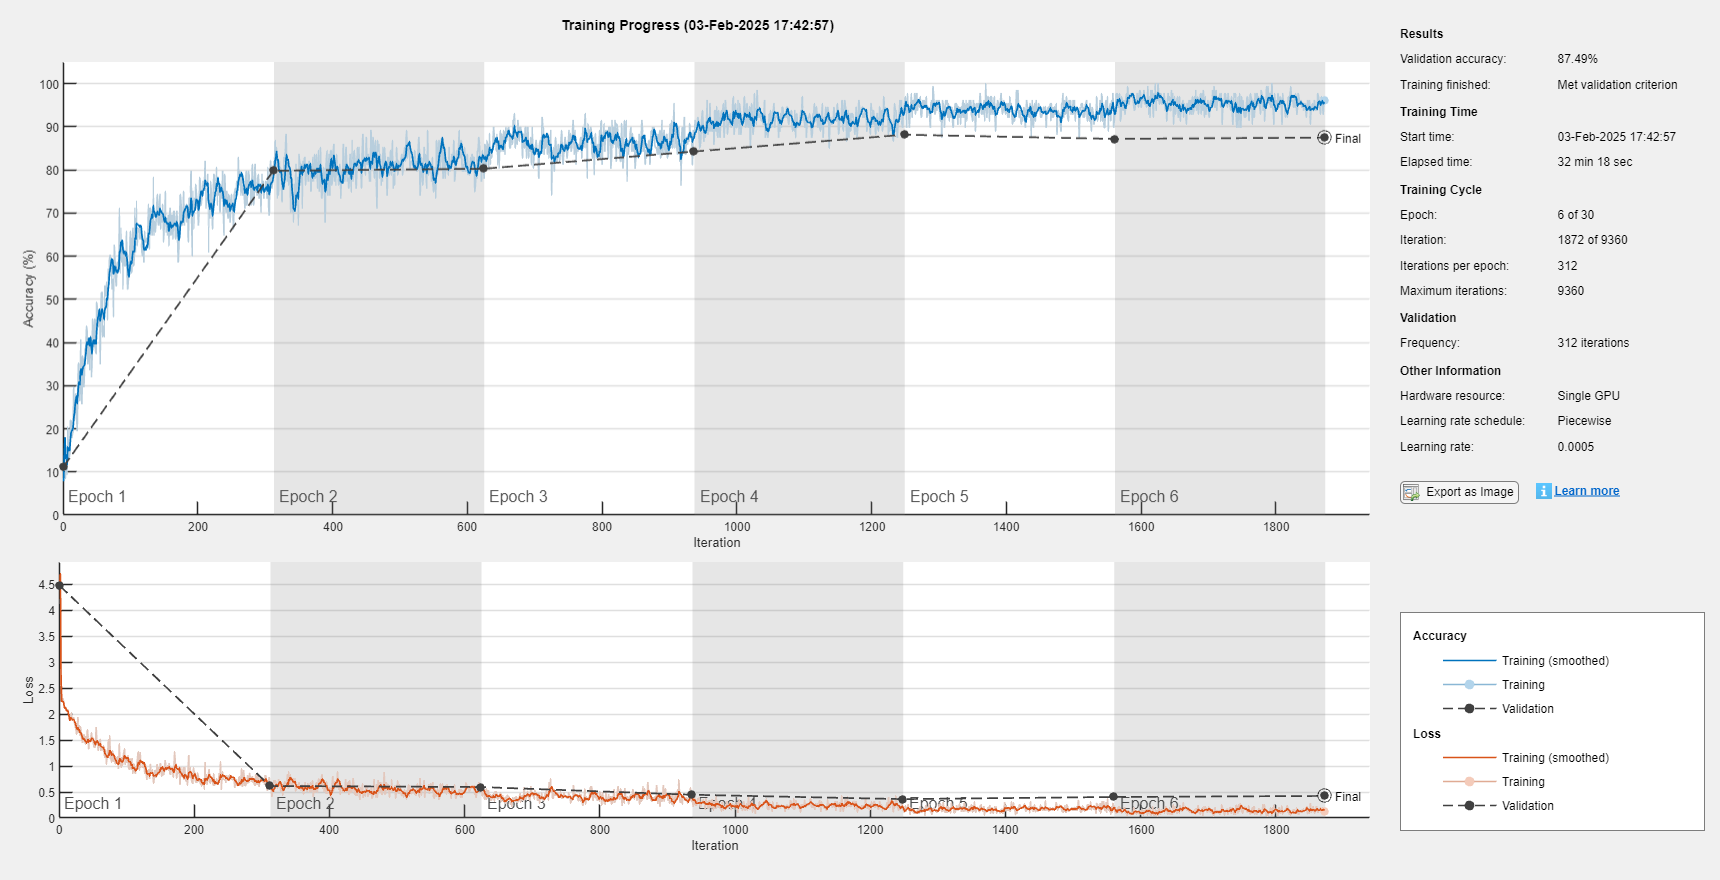

googlenetTrained = trainNetwork(trainData, lgraph, options);

disp('Entraînement de GoogLeNet terminé.');

Entraînement de GoogLeNet terminé.



%% 5. Évaluation des Performances du Modèle GoogLeNet

% Classification sur le jeu de test
[YPred, scores] = classify(googlenetTrained, testData);

% Calcul de l'accuracy
accuracy = mean(YPred == testLabels);
disp(['Accuracy de GoogLeNet : ', num2str(accuracy * 100), '%']);

Accuracy de GoogLeNet : 87.79%



% Calcul de la matrice de confusion
confMatrixRaw = confusionmat(testLabels, YPred);

% Calcul des métriques par classe
TP = diag(confMatrixRaw);
FP = sum(confMatrixRaw, 1)' - TP;
FN = sum(confMatrixRaw, 2) - TP;

precisionClass = TP ./ (TP + FP + eps);
recallClass    = TP ./ (TP + FN + eps);
f1Class        = 2 * (precisionClass .* recallClass) ./ (precisionClass + recallClass + eps);

% Affichage des métriques par classe
disp('Métriques par classe :');

Métriques par classe :


for i = 1:length(classNames)
    fprintf('Classe %s : Précision = %.2f%% | Rappel = %.2f%% | F1-score = %.2f%%\n', ...
        classNames(i), precisionClass(i)*100, recallClass(i)*100, f1Class(i)*100);
end

Classe airplane : Précision = 83.92% | Rappel = 92.40% | F1-score = 87.96%
Classe automobile : Précision = 93.00% | Rappel = 95.70% | F1-score = 94.33%
Classe bird : Précision = 81.24% | Rappel = 90.50% | F1-score = 85.62%
Classe cat : Précision = 83.84% | Rappel = 68.50% | F1-score = 75.40%
Classe deer : Précision = 84.33% | Rappel = 88.80% | F1-score = 86.51%
Classe dog : Précision = 80.97% | Rappel = 82.10% | F1-score = 81.53%
Classe frog : Précision = 90.95% | Rappel = 92.50% | F1-score = 91.72%
Classe horse : Précision = 92.29% | Rappel = 89.80% | F1-score = 91.03%
Classe ship : Précision = 96.36% | Rappel = 84.70% | F1-score = 90.15%
Classe truck : Précision = 92.62% | Rappel = 92.90% | F1-score = 92.76%



% Calcul des métriques globales
globalPrecision = sum(TP) / (sum(TP) + sum(FP) + eps);
globalRecall    = sum(TP) / (sum(TP) + sum(FN) + eps);
globalF1Score   = 2 * (globalPrecision * globalRecall) / (globalPrecision + globalRecall + eps);
errorRate = 1 - accuracy;

% Affichage des résultats globaux
disp(' ');

disp('Évaluation globale de GoogLeNet :');

Évaluation globale de GoogLeNet :


fprintf('Accuracy           : %.2f%%\n', accuracy * 100);

Accuracy           : 87.79%


fprintf('Précision globale  : %.2f%%\n', globalPrecision * 100);

Précision globale  : 87.79%


fprintf('Rappel global      : %.2f%%\n', globalRecall * 100);

Rappel global      : 87.79%


fprintf('F1-score global    : %.2f%%\n', globalF1Score * 100);

F1-score global    : 87.79%


fprintf('Taux d''erreur     : %.2f%%\n', errorRate * 100);

Taux d'erreur     : 12.21%


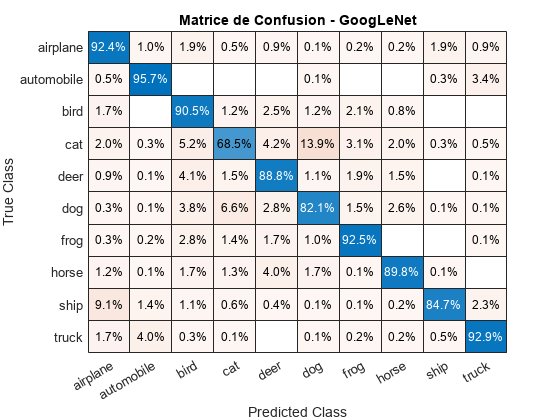


% Visualisation de la matrice de confusion
figure;
confusionchart(testLabels, YPred, 'Normalization','row-normalized');
title('Matrice de Confusion - GoogLeNet');

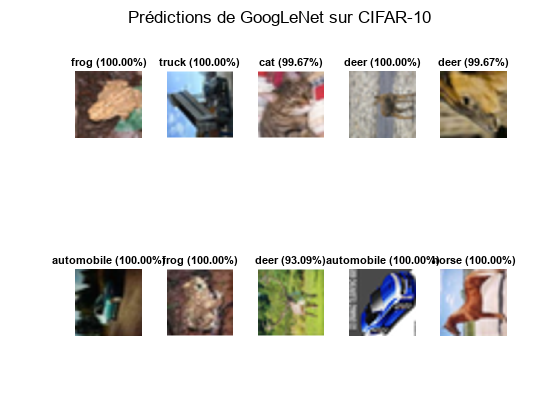


%% 6. Visualisation des Prédictions de GoogLeNet
figure;
numImagesToShow = 10;
indices = randperm(numTestImages, numImagesToShow);

for i = 1:numImagesToShow
    subplot(2, 5, i);
    img = testImagesResized(:,:,:, indices(i));
    imshow(uint8(img));
    
    [maxProb, maxIdx] = max(scores(indices(i), :));
    title(sprintf('%s (%.2f%%)', classNames(maxIdx), maxProb * 100));
end
sgtitle('Prédictions de GoogLeNet sur CIFAR-10');